# Plot Path Gains for TDL-E Delay Profile with SISO

tdl = nrTDLChannel;
tdl.SampleRate = 500e3;
tdl.MaximumDopplerShift = 70;
tdl.DelayProfile = 'TDL-E';

tdl.NumTransmitAntennas = 1;
tdl.NumReceiveAntennas = 1;

in = zeros(1000,tdl.NumTransmitAntennas);

[~, pathGains] = tdl(in);

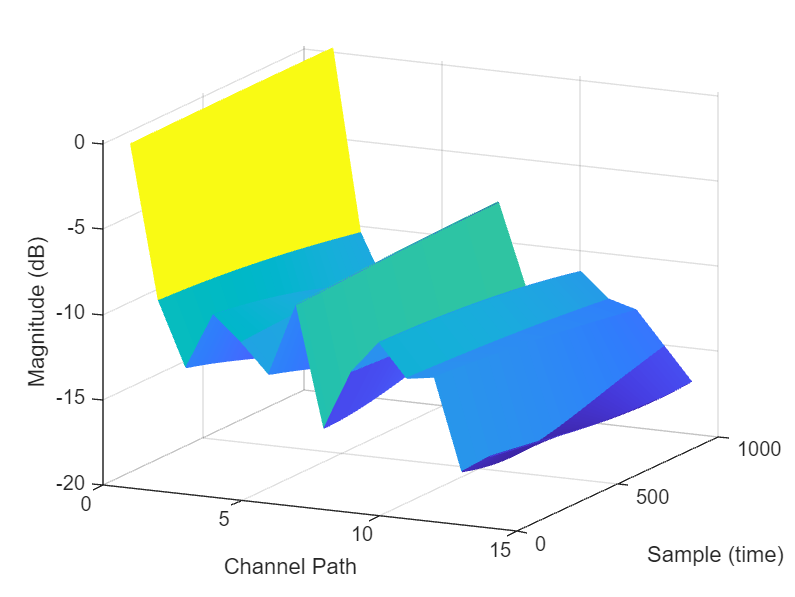

mesh(10*log10(abs(pathGains)));
view(26,17); xlabel('Channel Path');
ylabel('Sample (time)'); zlabel('Magnitude (dB)');